# **Matlab案例代码解析**

## 3. 科学计算案例

### 3.1 数值分析

#### 3.1.6 CVX工具箱求解凸优化问题

颜值即正义；

**颜色模板参考：**[**60套优雅的颜色模板**](https://zhuanlan.zhihu.com/p/444970597)

CVX工具箱下载地址：[Download CVX](http://cvxr.com/cvx/download/)

使用方法：下载压缩包之后解压到常用目录，命令行输入 cvx_setup 回车，无错误提示即可使用。

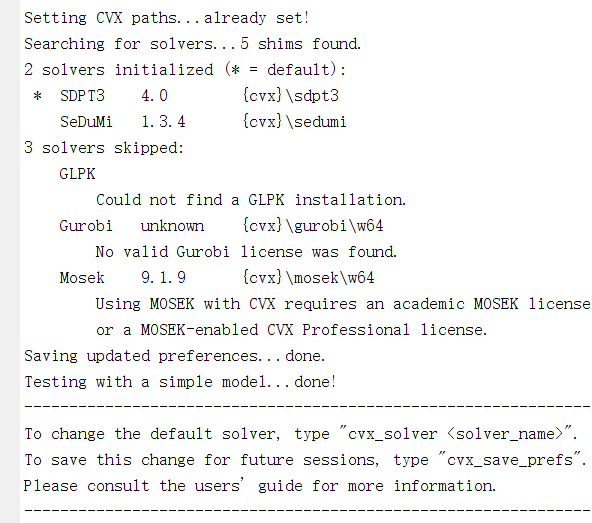

官网 Demo 检验：

clear;clc;
m = 20; 
n = 10; 
p = 4;
A = randn(m, n); 
b = randn(m, 1);
C = randn(p, n);
d = randn(p, 1); 
e = rand;
cvx_begin
    variable x(n)
    minimize( norm( A * x - b, 2 ) )
    subject to
        C * x == d
        norm( x, Inf ) <= e
cvx_end

 
Calling SDPT3 4.0: 56 variables, 22 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 22
 dim. of socp   var  = 41,   num. of socp blk  = 11
 dim. of linear var  = 11
 dim. of free   var  =  4 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|1.4e+01|1.1e+01|3.4e+03| 4.072609e+00  0.000000e+00| 0:0:00| chol  1  1 
 1|0.943|0.438|7.9e-01|6.4e+00|8.2e+02| 6.342932e+00 -4.062499e+00| 0:0:01| chol  1  1 
 2|1.000|0.954|2.2e-05|3.0e-01|3.8e+01| 6.514754e+00 -3.435835e+00| 0:0:01